# D. Anharmonic oscillator

clear; close all;
z0 = 1e-6;  % beam width of 1um

I will choose $\Delta z = z_0/10$ and $z_{max} = 10z_0$

deltaZ = z0/10;     % step size
zmax = 10*z0;       % maximum grid extent
N = zmax/deltaZ + 1;        % number of points in grid

This means that there will be 101 eigenvalue/eigenvector pairs for `eigs` to compute.

mu = 1:N;
z_mu = -zmax/2 + (mu -1)*deltaZ;
h = zeros(N,N);
% create the hamiltonian matrix h
for i = 1:N
    for j = 1:N
        if i == j
            h(i,j) = (1/2)*(z_mu(i)/z0).^2 + (z0/deltaZ)^2;
        elseif i ==(j+ 1) || i == (j - 1)
            h(i,j) = -(1/2)*(z0/deltaZ)^2;
        end
    end
end

#### D. Anharmonic oscillator


$$\Psi(z,t) = \sum\limits_{j=0}^{\infty} c_{j}\psi_{j}(z)e^\frac{-iE_{j}t}{\hbar}$$



$$c_{j} = \int_{-\infty}^{\infty}dz\; \psi_{j}^{*}\Psi(z,0)$$


Displaced wavefunction


$$\Psi_{\mu}(0) = \mathcal{N}_{0}\exp[-(z_{\mu} - 2z_{0})^{2}/2z_{0}^{2}]$$


a.) We want to make a 2D plot with respect to $\omega t$ and $\mu$ for the displaced wavefunction.

    1. Find the expansion coefficients

    2. Fill in the $E_j$ eigenvalues with the form $E_j = \hbar\omega(j + 1/2)$

    3. find $\Psi(z,t)$

    4. Plot $\Psi(z,t)$ 

1.) find expansion coefficients. To do this, we need to discretize the continuous expression above. 


$$\int_{-\infty}^{\infty} dz\; \psi_{j}^{*}(z)\Psi(z,0) \rightarrow \sum\limits_{\mu}\Delta z (\psi_{j}^{*})_{\mu}\Psi_{\mu}(0) = c_{j}$$


With this in mind, we should be able to find the set of expansion coefficients as follows: 

**Aside Working on meshgrid stuff.**

**define a time vector and an **$z_\mu$ vector for the meshgrid.

% wt1 = linspace(1,40,N);
% [WT1,Z_mu] = meshgrid(wt1,z_mu);

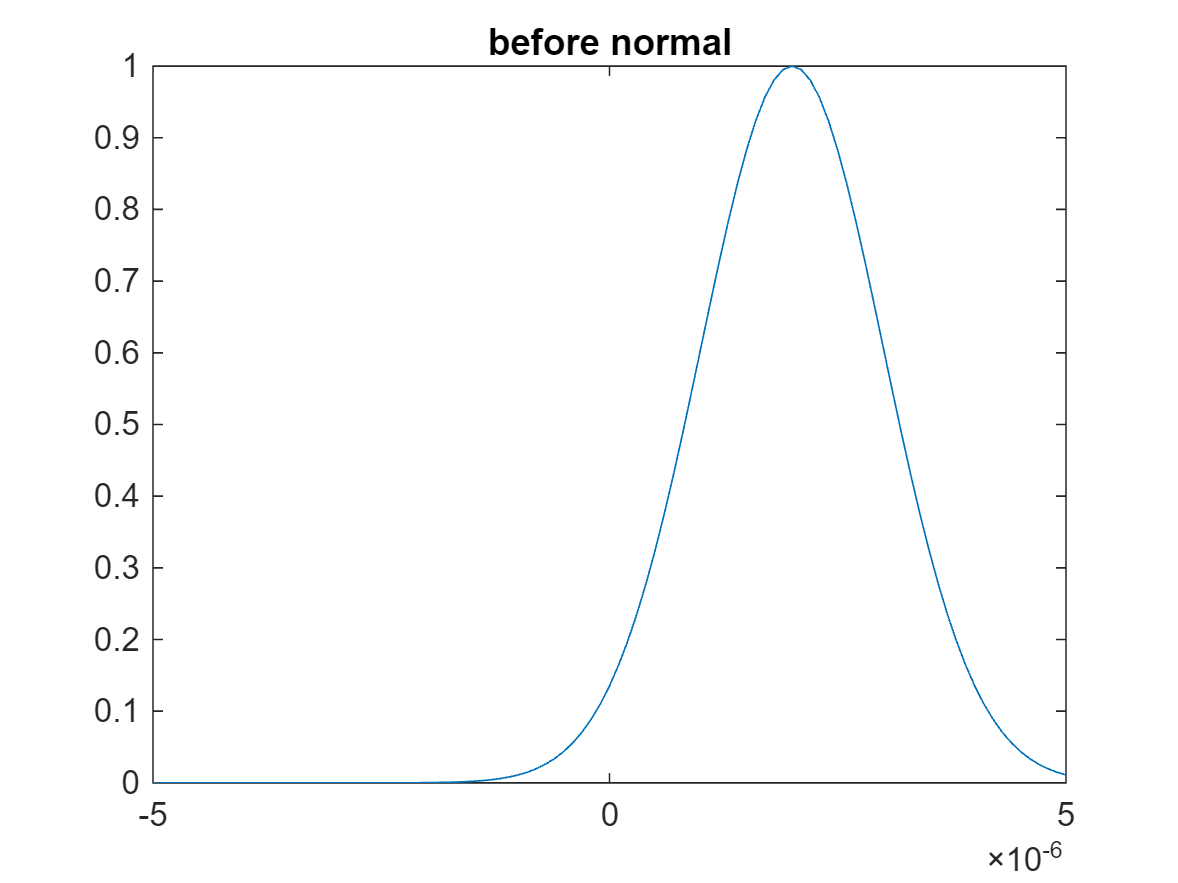

[V,~] = eigs(h,N,'smallestabs');
Ej = eigs(h,N,'smallestabs');
psi = V./sqrt(deltaZ); % from previous sections, we know this is the correct way to represent the wavefunction given the normalized eigenvectors
N0 = (1./(pi*z0^2)).^(1/4);
PSI0 = exp(-1*((z_mu - 2*z0).^2)./(2*z0^2))';
plot(z_mu,PSI0);
title('before normal');

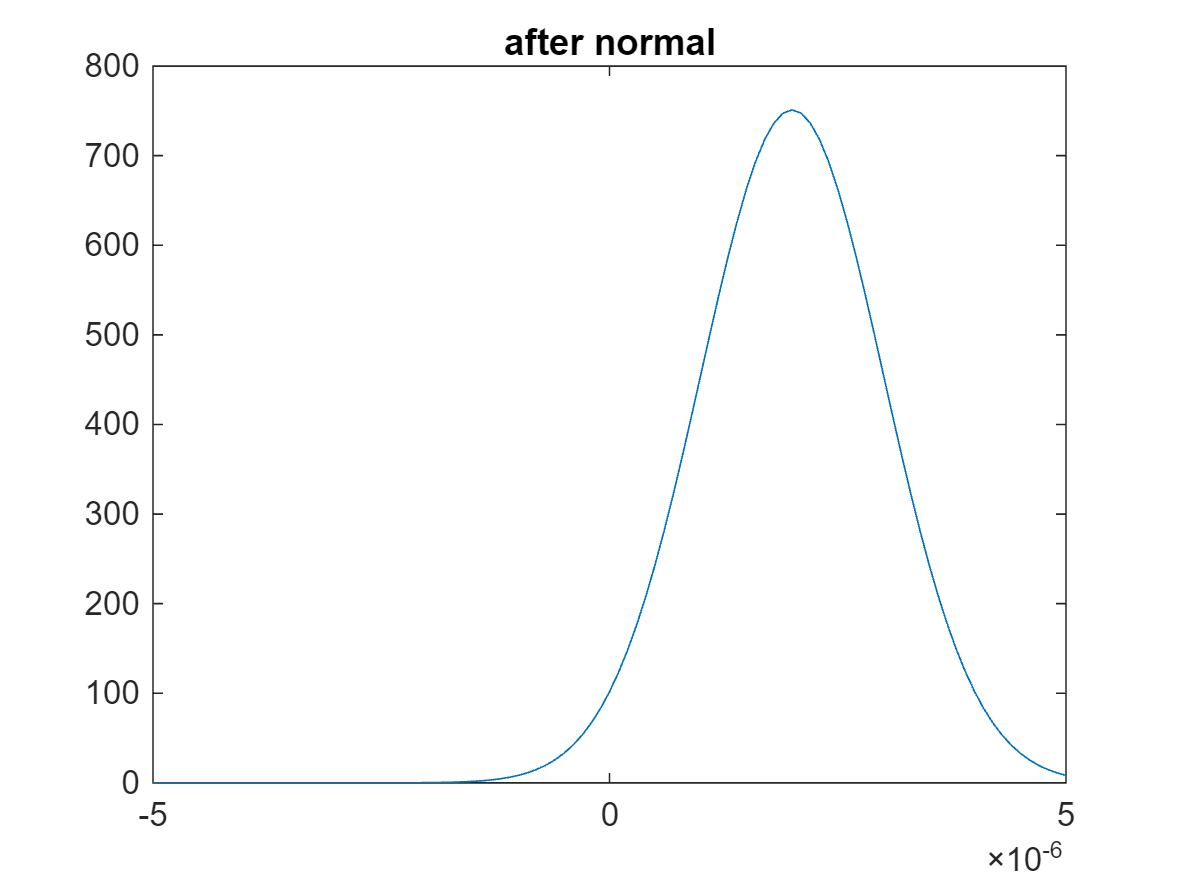

PSI0 = N0.*PSI0;
plot(z_mu,PSI0);
title('after normal');

%%% Potential meshgrid option
% PSI0_mesh = (N0.*exp(-(Z_mu - 2*z0).^2/2/z0^.2))';
% Cj = psi'*PSI0_mesh*deltaZ;
%%%%%5
cj = psi'*PSI0*deltaZ;

Important to realize is that since the hamiltonian for which we found the eigenvectors and and eigenvalues has $\hbar\omega$ factored out, we must consider this when we go about trying to write the time dependent form of the wavepacket.

If we write $E_{j}$  as  


$$e_{j} = \hbar\omega E_{j}$$


and 


$$\exp[-ie_{j}t/\hbar]\rightarrow\exp[-i\omega t E_{j}]$$


where $E_{j}= j + 1/2$ then it becomes straightforward how to inject time dependence.

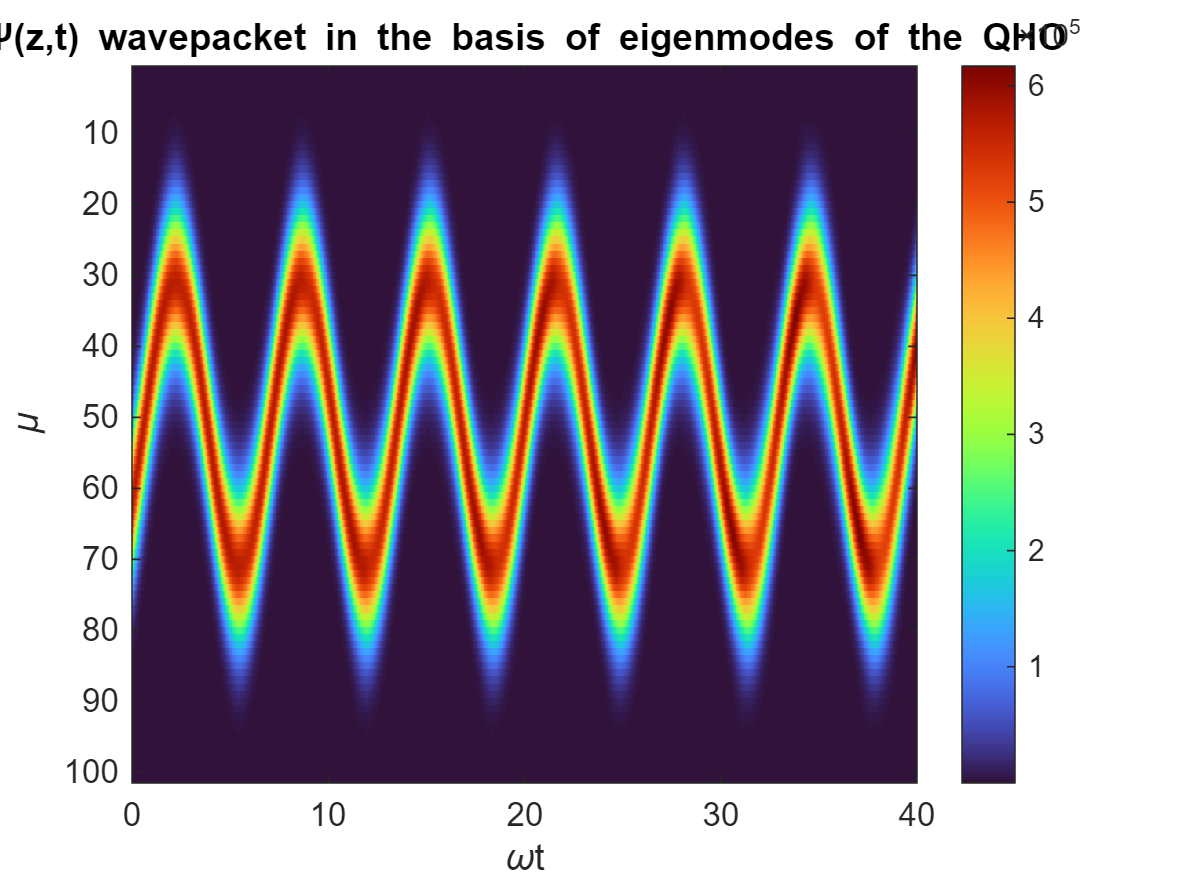

wt = linspace(1,40,1000); % effective time vector
% wt = 1:40;
PSI_temp = zeros(length(cj),length(wt));
PSI = zeros(length(cj),length(wt));

for j = 1:length(cj)
    for k = 1:length(wt)
        PSI_temp(:,k) = cj(j)*psi(:,j)*exp(-1i*wt(k)*Ej(j));
    end
    if j == 1 
        PSI = PSI_temp;
    else
        % sum up the weighted eigenvectors
        PSI = PSI + PSI_temp;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%
% PSI_temp_mesh = zeros(length(cj),length(wt));
% PSI_mesh = zeros(length(cj),length(wt));
% 
% for j = 1:length(Cj)
%     for k = 1:length(WT1)
%         PSI_temp_mesh(:,k) = Cj(j)*psi(:,j)*exp(-1i*WT1(k)*Ej(j));
%     end
%     if j == 1 
%         PSI_mesh = PSI_temp_mesh;
%     else
%         % sum up the weighted eigenvectors
%         PSI_mesh = PSI_mesh + PSI_temp_mesh;
%     end
% end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(4);
imagesc([0,40],[],abs(PSI).^2);
xlabel('\omegat');
ylabel('\mu');
title('\Psi(z,t) wavepacket in the basis of eigenmodes of the QHO')

colormap turbo;
colorbar;

b.) plotting expectation values

$\langle z(t) \rangle/z_0 = 2\cos(\omega t )$ analytically 

To calculate the expectation value numerically, we need to take its definition


$$\langle z(t) \rangle = \langle \Psi(z,t) | z|\Psi(z,t)\rangle = \int_{-\infty}^{\infty} \Psi^{*}(z,t)z\Psi(z,t)\;dz$$
 

and discretize it :


$$\int_{-\infty}^{\infty} \Psi^{*}(z,t)z\Psi(z,t)\;dz \rightarrow \sum\limits_{\mu}\Delta z\Psi^{*}_{\mu}z_{\mu}\Psi_{\mu}$$


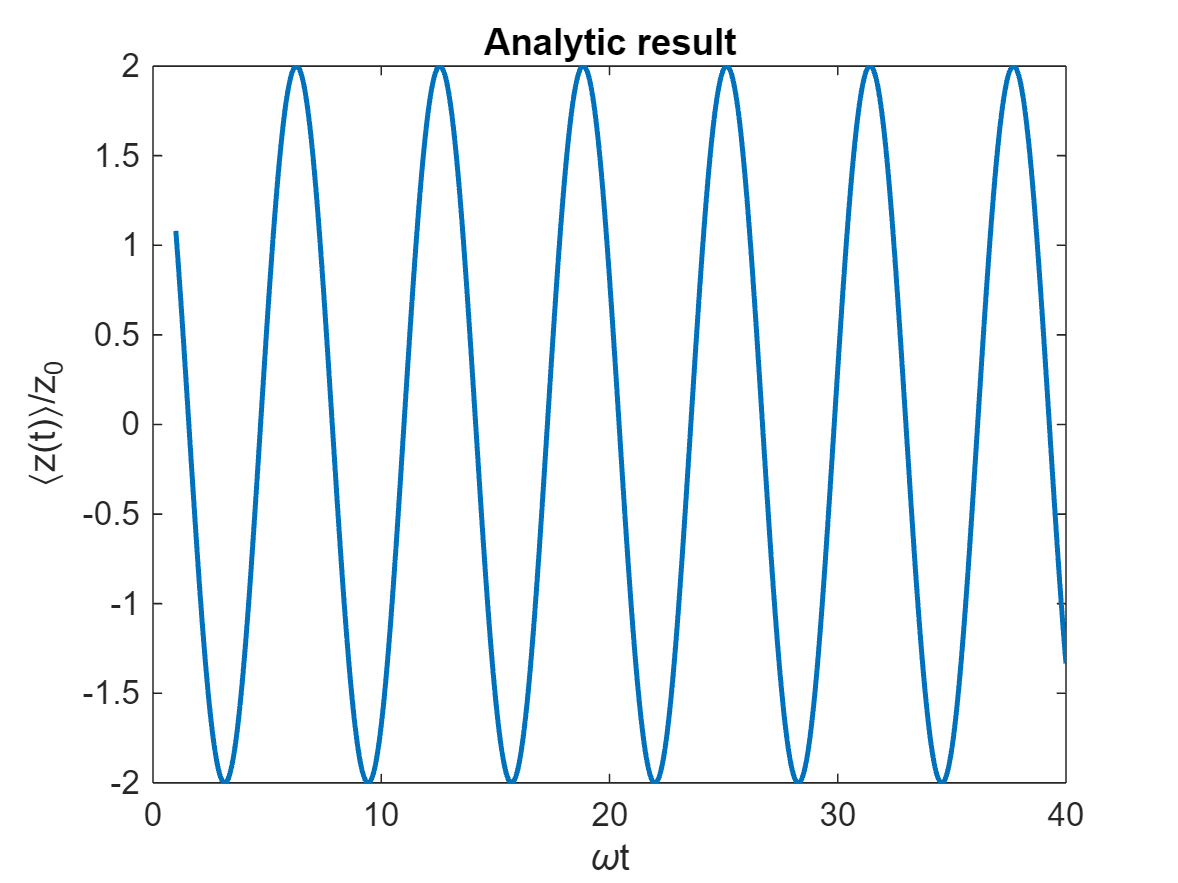

% analytic
braket_z_a = 2*cos(wt);

figure(5);
plot(wt,braket_z_a,'LineWidth',1.5);
title('Analytic result');
ylabel('\langlez(t)\rangle/z_0')
xlabel('\omegat');

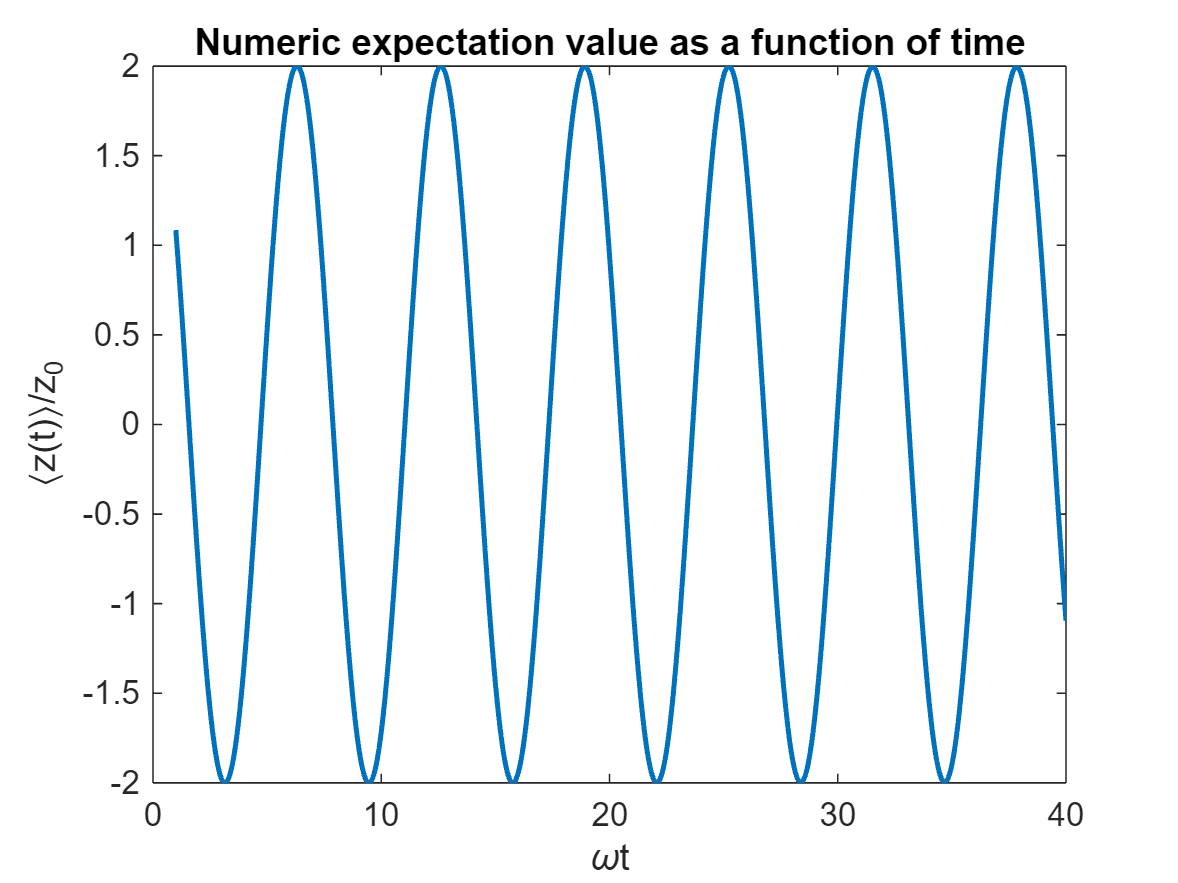

%% %% something is going wrong here.
% numeric
braket_z_n = zeros(1,length(wt));
PSI_conj = conj(PSI);
PSI;
for i = mu
     braket_z_n =  braket_z_n + deltaZ*z_mu(i).*abs(PSI(i,:)).^2;
end
braket_z_n = braket_z_n/z0;
figure(6);
plot(wt,real(braket_z_n),'LineWidth',1.5);
title('Numeric expectation value as a function of time')
ylabel('\langlez(t)\rangle/z_0');
xlabel('\omegat');

c.) Add anharmonicity to the harmonic oscillator.


$$V_{\mu} = \frac{1}{2}(z_{\mu}/z_{0})^{2}\rightarrow \frac{1}{2}(z_{\mu}/z_{0})^{2} + 0.02(z_{\mu}/z_{0})^{4}$$


This means that the normalized hamiltonian becomes


$$h_{\mu,\nu} = \frac{H_{\mu,\nu}}{\hbar\omega} = \bigl[\frac{1}{2}(z_{\mu}/z_{0})^{2} + 0.02(z_{\mu}/z_{0})^{4} + (z_{0}/\Delta z)^{2}\bigl]\delta_{\mu,\nu} - \frac{1}{2}(z_{0}/\Delta z)^{2}[\delta_{\mu,\nu+1} + \delta_{\mu,\nu-1}]$$


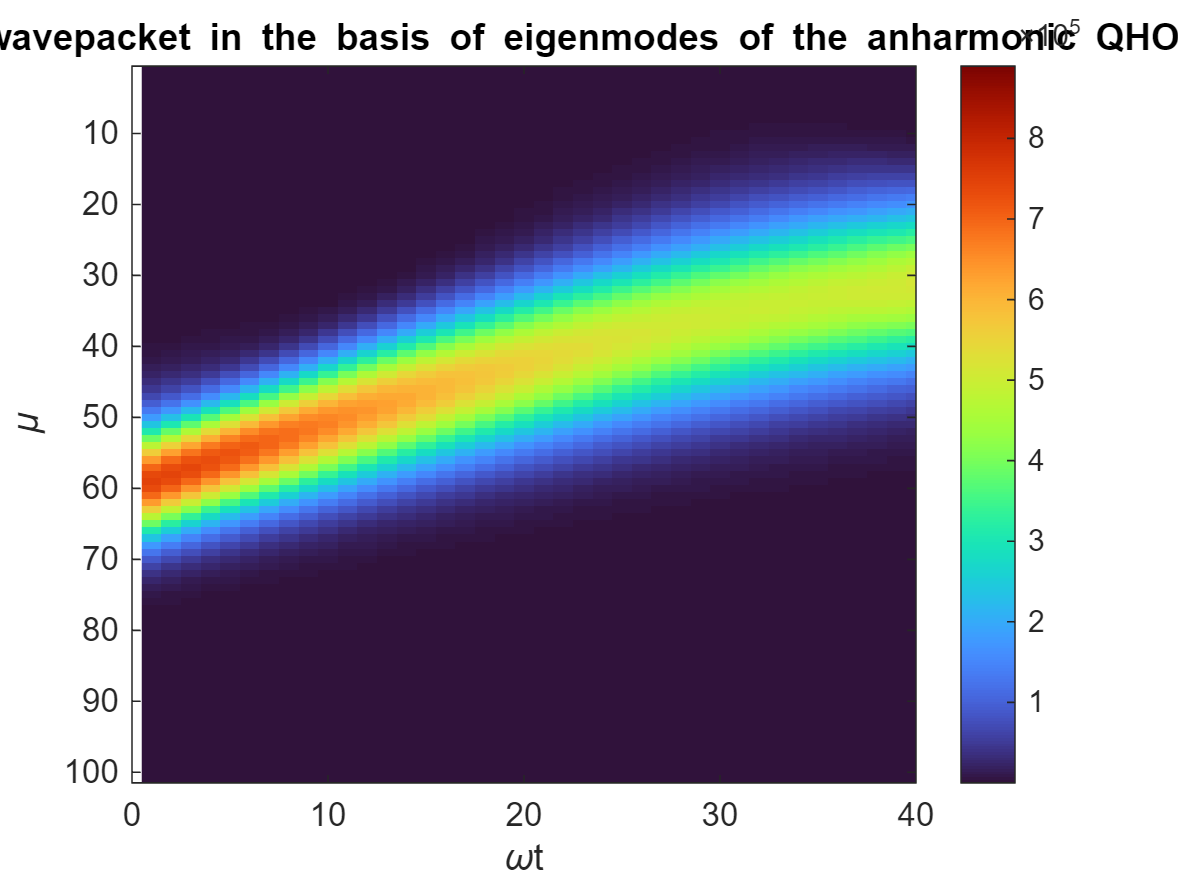

% clear psi V Ej PSI0 PSI PSI_temp cj
% Fill out the anharmonic hamiltonian matrix
h_a = zeros(N,N);
% create the hamiltonian matrix h
for i = 1:N
    for j = 1:N
        if i == j
            h_a(i,j) = (1/2)*(z_mu(i)/z0)^2 + 0.02*(z_mu(i)./z0).^(4) + (z0/deltaZ)^2;
        elseif i ==(j+ 1) || i == (j - 1)
            h_a(i,j) = -(1/2)*(z0/deltaZ)^2;
        end
    end
end

% get eigenvalues and eigen vectors
[V,~] = eigs(h_a,N,'smallestabs');
Ej_a = eigs(h_a,N,'smallestabs'); 
% fix normalization condition
psi_a = V./sqrt(deltaZ); % from previous sections, we know this is the correct way to represent the wavefunction given the normalized eigenvectors
% define the analytic normalization constant
N0 = (1/pi/z0^2)^(1/4);
PSI_a = exp(-1*((z_mu - 2*z0).^2)./(2*z0^2))';
% displaced wavefunction
PSI_a = N0.*PSI_a;
% get the expansion coefficients.
cj_a = psi_a'*PSI_a*deltaZ; 

PSI_temp_a = zeros(length(cj_a),length(wt));
PSI_a = zeros(length(cj_a),length(wt));

% inject time dependence.
for j = 1:length(cj_a)
    for k = 1:length(wt)
        PSI_temp_a(:,k) = cj_a(j)*psi_a(:,j)*exp(-1i*wt(k)*Ej_a(j));
    end
    if j == 1 
        PSI_a = PSI_temp_a;
    else
        % sum up the weighted eigenvectors
        PSI_a = PSI_a + PSI_temp_a;
    end
end
figure(7);
imagesc(abs(PSI_a).^2);
xlabel('\omegat');
ylabel('\mu');
title('\Psi(z,t) wavepacket in the basis of eigenmodes of the anharmonic QHO');
colormap turbo;
colorbar;
xlim([0,40]);

d.) plotting anharmonic expectation values.

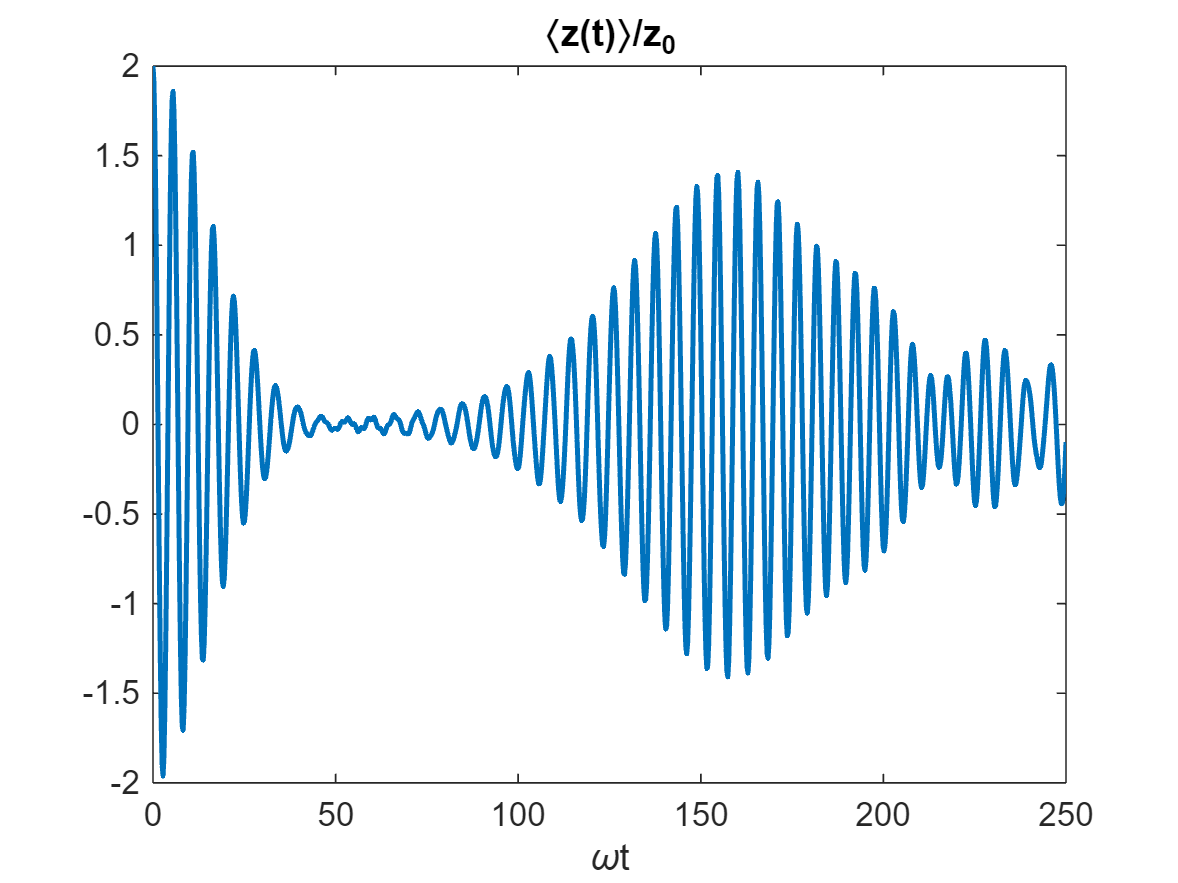

wt1 = linspace(0,250,1000);
% inject time dependence.
for j = 1:length(cj_a)
    for k = 1:length(wt1)
        PSI_temp_a(:,k) = cj_a(j)*psi_a(:,j)*exp(-1i*wt1(k)*Ej_a(j));
    end
    if j == 1 
        PSI_a = PSI_temp_a;
    else
        % sum up the weighted eigenvectors
        PSI_a = PSI_a + PSI_temp_a;
    end
end

braket_z_n_a = zeros(1,length(wt1));
PSI_conj_a = conj(PSI_a);
PSI;
for i = mu
     braket_z_n_a =  braket_z_n_a + z_mu(i).*abs(PSI_a(i,:)).^2;
end
braket_z_n_a = braket_z_n_a*deltaZ/z0;
figure(8);
plot(wt1,real(braket_z_n_a),'LineWidth',1.5);
title('\langlez(t)\rangle/z_0');
xlabel('\omegat');